# Ephaptic Coupling in Two Cortical Interneurons

## Model Set Up

warning('off', 'all')
cell = ELFENN.Geometry.load_swc('P7i_WT3.CNG.swc');
warning('on', 'all')
cell.name = 'cell1';
network = ELFENN.Network();
network.addcell(cell);

cell.name = 'cell2';
cell.rotatecell([0, pi, 0], [0, 0, 0])
network.addcell(cell, [140, 0, 0]);
network.complete();
network.assignsolutionindex("Vm","m","h","n","q");

synapse_params = ELFENN.Mechanisms.Synapse.Alpha.default_parameters;
synapse_params.tau = 3;
synapse_params.gSyn = 5;
synapse_params.t0 = 5;
network.addexternalsynapse(network.getcellbyname('cell1').soma,...
@ELFENN.Mechanisms.Synapse.Alpha.s, synapse_params, 'unscaled');

sigma = 0.01;
IC = [-69.7548 0.05, 0.59 0.31 0.0002];
network.setdynamics(ELFENN.Mechanisms.Cellular.FS.default_parameters());
solver = ELFENN.Supervisor(@ELFENN.Mechanisms.Cellular.FS.ode, network, IC, sigma);

solver.ephapticStatus = 'on';
solver.tmax = 15;
solver.rtol = 1e-3;
solver.transientLength = 2;
[t,y] = solver.run();

## Special Indeces

[~, soma] = network.segmentclosestto([0, 0, 0]);
[~, bottom_seg] = network.segmentclosestto([69, 23.7, -2]);
[~, edge_seg] = network.segmentclosestto([55, 47, -2]);
ix_used = find(t < 10);

## Panel A

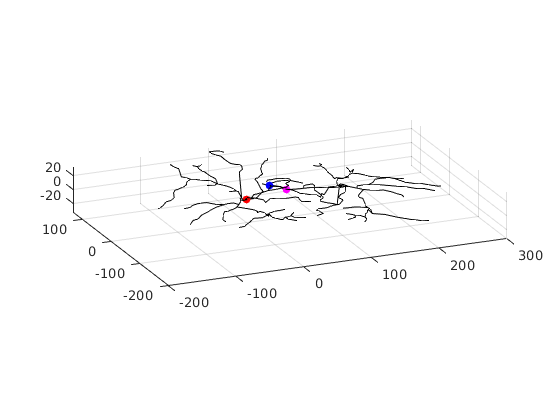

hold all
plotnetwork(network, 'style', 'line')
scatter3(soma.position(1), soma.position(2), soma.position(3),'r', 'filled')
scatter3(bottom_seg.position(1), bottom_seg.position(2), bottom_seg.position(3),'m', 'filled')
scatter3(edge_seg.position(1), edge_seg.position(2), edge_seg.position(3),'b', 'filled')    
view([-23, 19]);
grid on
set(gcf, 'color', 'white');
box off

## Panel B

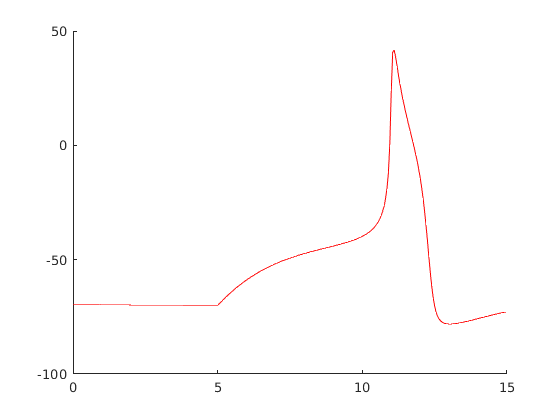

figure;
hold all
plot(t, y(:, soma.ODEID.Vm),'r');    
plot([t(ix_used(end)), t(ix_used(end))], [-85, 50], 'k--');  

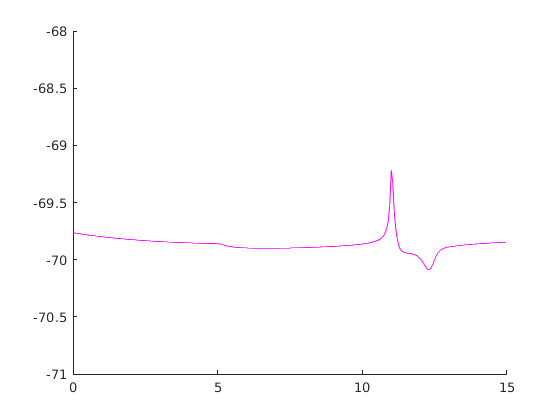


figure;
hold all
plot(t, y(:, bottom_seg.ODEID.Vm),'m');   
plot([t(ix_used(end)), t(ix_used(end))], [-71, -68], 'k--');   

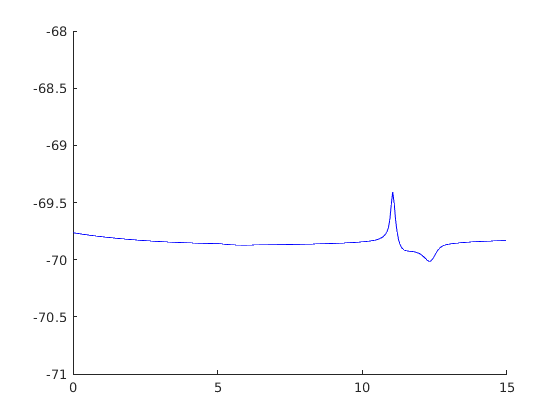

  
figure;
hold all
plot(t, y(:, edge_seg.ODEID.Vm),'b');
plot([t(ix_used(end)), t(ix_used(end))], [-71, -68], 'k--');    

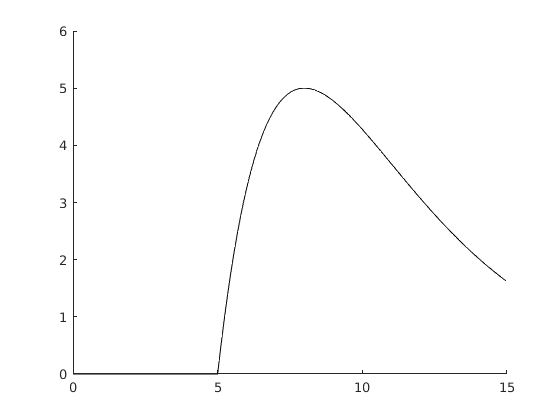


i_syn = recreate_synaptic_current(t, synapse_params, @ELFENN.Mechanisms.Synapse.Alpha.s);
figure;
hold all
plot(t, i_syn,'k');
plot([t(ix_used(end)), t(ix_used(end))], [0, 5], 'k--');

## Panel C

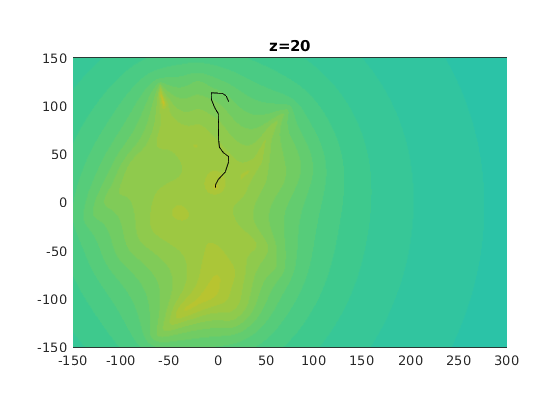

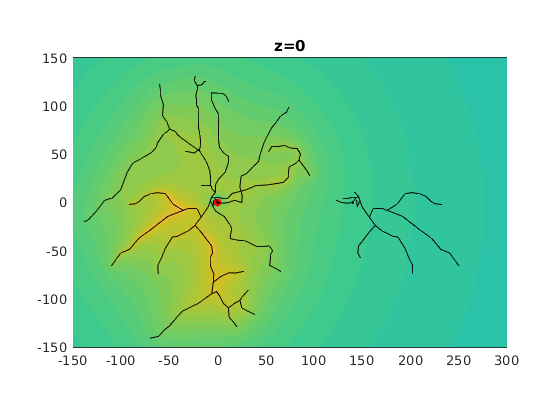

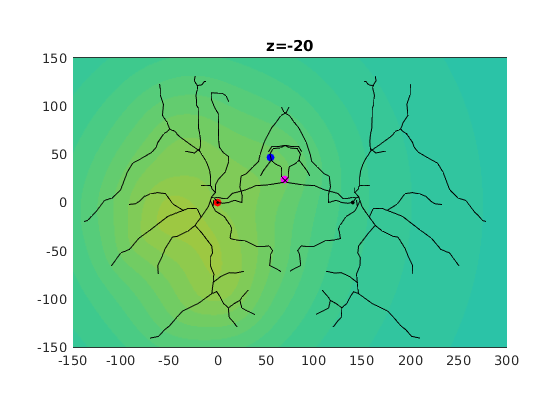

Im = solver.reconstruct_I_trans(t, y);
membraneCurrent = Im(ix_used(end),:);

x_bounds = [-150, 300];
x_res = 1;
y_bounds = [-150 150];
y_res = 1;
z_res = 1;
offsets = [20, 0 -20];
for ix = 1:length(offsets)
    figure;
    z_bounds = [offsets(ix) offsets(ix)]; % we only want 1 plane
    [x_electrode, y_electrode, z_electrode] = generate_electrode_grid(x_bounds, x_res, y_bounds, y_res, z_bounds, z_res);    
    LFP = get_lfp_snapshot(network, membraneCurrent, x_electrode, y_electrode, z_electrode, sigma);
    plotLFP(network, LFP, x_electrode, y_electrode, z_bounds(1), 0)     
    plotnetwork(network, 'style', 'line')
    scatter3(soma.position(1), soma.position(2), soma.position(3),'r', 'filled')
    scatter3(bottom_seg.position(1), bottom_seg.position(2), bottom_seg.position(3),'m', 'filled')
    scatter3(edge_seg.position(1), edge_seg.position(2), edge_seg.position(3),'b', 'filled')
    caxis([-0.5, 0.5]);  
    title("z="+offsets(ix))
end